format longg

[p, q] = Appcat(2022);
disp(p + "/" + q);

109/119


disp(p / q);

         0.915966386554622



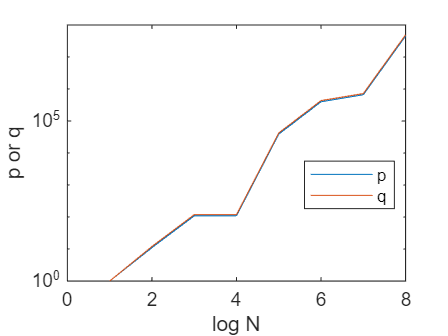


n = 8;
ps = zeros(1, n);
qs = zeros(1, n);
for i = 1 : n
    [p, q] = Appcat(10 ^ i);
    ps(i) = p;
    qs(i) = q;
end
figure;
semilogy(1 : n, ps);
hold on
semilogy(1 : n, qs);
legend("p", "q", "Location", "best");
xlabel("log N")
ylabel("p or q")
hold off


n = 36031;
[a, b, c, d, M] = CubicTaxicabNum(n);
disp("Minimal Integer above " + n + ":")

Minimal Integer above 36031:


disp(M + " = " + a + " ^ 3 + " + b + " ^ 3");

39312 = 2 ^ 3 + 34 ^ 3


disp(M + " = " + c + " ^ 3 + " + d + " ^ 3");

39312 = 15 ^ 3 + 33 ^ 3



tic
[map, M] = CubicTaxicabNum2(1);
disp(map);

     1     1



disp("Found T_1 = " + M);

Found T_1 = 2



tic
[map, M] = CubicTaxicabNum2(2);
disp(map);

     1    12
     9    10



disp("Found T_2 = " + M );

Found T_2 = 1729



tic
[map, M] = CubicTaxicabNum2(3);
disp(map);

   167   436
   228   423
   255   414



disp("Found T_3 = " + M);

Found T_3 = 87539319



% 87539319

**Task A:**

function [p, q] = AppCat(N)
    catconst = 0.915965594177219;
    catconst_ceil = 0.915965594177220;

    p = 1;
    q = 1;
    for i = 1 : N
        low = floor(catconst * i);
        high = ceil(catconst_ceil * i);
        if i + low > N
            break;
        end
        for j = low : high
            if abs(p / q - catconst) > abs(j / i - catconst) && i + j <= N
                p = j;
                q = i;
            end
        end
    end
end

Analytically:

function [a, b, c, d, M] = CubicTaxicabNum(N)
    % persistent cache;
    % if ~exist('cache', 'var')
    %     cache = [];
    %     for i = max(1, length(cache) + 2) : ceil(N ^ (1 / 3))
    %         cache(i) = i ^ 3;
    %     end
    % end

    a = 0;
    b = 0;
    k = N;
    while true
        found = [false, false];
        for i = 1 : floor((k / 2) ^ (1 / 3))
            ap = i ^ 3;
            bp = round((k - ap) ^ (1 / 3));
            if bp == 0
                continue;
            end
            if ap + bp ^ 3 == k
                if found(1)
                    c = i;
                    d = bp;
                    found(2) = true;
                    break;
                end
                a = i;
                b = bp;
                found(1) = true;
            end
        end
        if sum(found) == 2
            M = k;
            return;
        end
        k = k + 1;
    end
end

sd

function [map, M] = CubicTaxicabNum2(n)
    if n == 3
        k = 87539319;% 87539319;
    else
        k = 1;
    end
    map = zeros(n, 2);
    while true
        found = zeros(1, n);
        nx = 1;
        for i = 1 : floor((k / 2) ^ (1 / 3))
            ap = i ^ 3;
            bp = round((k - ap) ^ (1 / 3));
            if bp == 0
                continue;
            end
            if ap + bp ^ 3 == k
                map(nx, 1) = i;
                map(nx, 2) = bp;

                found(nx) = true;
                nx = nx + 1;
                if nx > n
                    break;
                end
            end
        end
        if sum(found) == n
            M = k;
            return;
        end
        k = k + 1;
    end
end

asdf

function [p, q] = AppCat_Analytical(N)
    res = sym(0);
    for i = 1: ceil(log10(N) / 3) + 1
        k = sym(i);
        res = res + sym(256)^k*(580*k^2-184*k+15)/(k^3*(2*k-1)*nchoosek(6*i,3*i)*nchoosek(6*i,4*i)*nchoosek(4*i,2*i)*64);
    end
    vpa(res, 20)

    p = sym(1);
    q = sym(1);
    for i = 1 : N
        low = floor(res * i);
        high = ceil(res * i);
        for j = low : high
            if abs(p / q - res) > abs(sym(j) / sym(i) - res)
                p = j;
                q = i;
            end
        end
    end

    p = vpa(p);
    q = vpa(q);
end